%slip5
Fs=10000;
T=1/Fs;
L=10000;
t=(0:L-1)*T;
f1=50;
f2=150;
f3=300;
signal=0.7*sin(2*pi*f1*t)+1.2*sin(2*pi*f2*t)+0.5*sin(2*pi*f3*t)+0.5*randn(size(t));

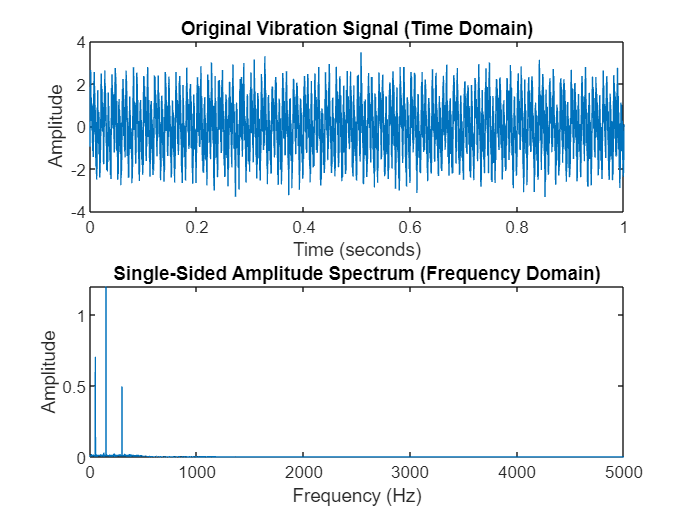


fc = 500; 
[b,a] = butter(4, fc/(Fs/2), 'low'); 
filtered_signal = filtfilt(b, a, signal); 


Y = fft(filtered_signal); 
P2 = abs(Y/L); 
P1 = P2(1:L/2+1); 
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

figure;
subplot(2,1,1);
plot(t, signal);
title('Original Vibration Signal (Time Domain)');
xlabel('Time (seconds)');
ylabel('Amplitude');

subplot(2,1,2);
plot(f, P1);
title('Single-Sided Amplitude Spectrum (Frequency Domain)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');



threshold = 0.3;
[peaks, locs] = findpeaks(P1, 'MinPeakHeight', threshold);

disp('Detected Frequencies (Hz) with potential anomalies:');

Detected Frequencies (Hz) with potential anomalies:


disp(f(locs));

    50   150   300




rms_value = rms(filtered_signal);
disp(['RMS Value of the Vibration Signal: ', num2str(rms_value)]);

RMS Value of the Vibration Signal: 1.0537



safe_rms_threshold = 0.8;
if rms_value > safe_rms_threshold
    disp('Warning: Excessive vibrations detected. Maintenance required.');
else
    disp('System is operating within safe vibration levels.');
end